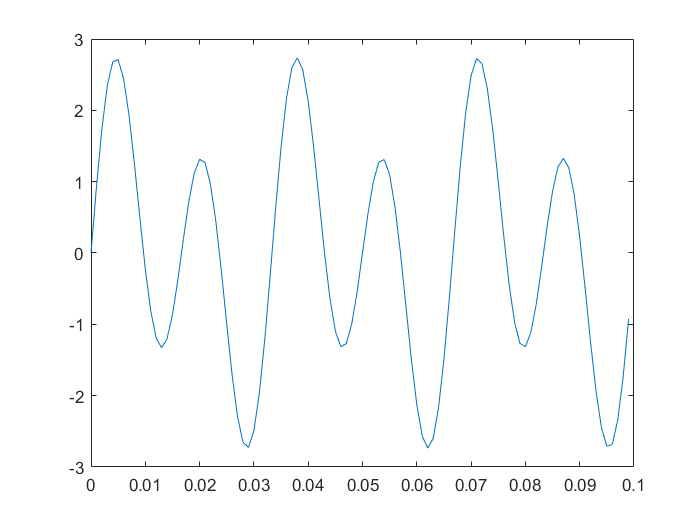

%%  学习目标：掌握一些典型的序列信号
%%  正弦信号和添加白噪声
clear all;close all;
t=(0:0.001:1);%时间0到1步进0.001
y=sin(2*pi*30*t)+2*sin(2*pi*60*t);   %原始信号
plot(t(1:100),y(1:100));%绘图，取前面100个点

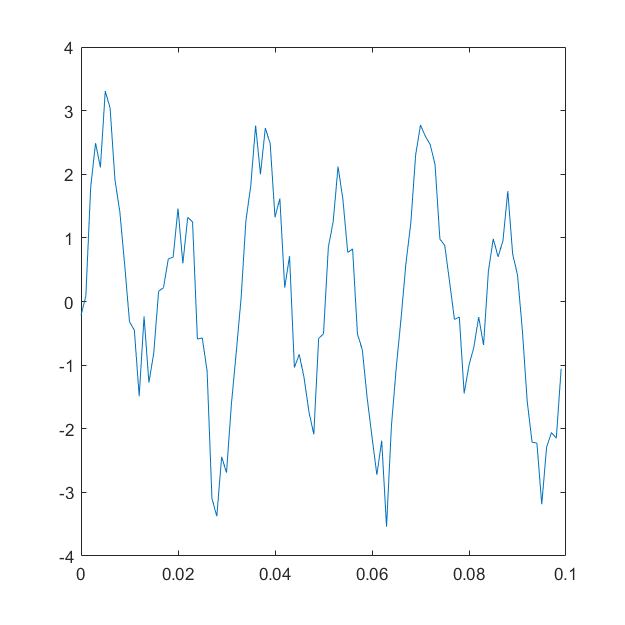

randn('state',0);%生成随机信号   
yn=y+0.5*randn(size(t));      %添加噪声信号
plot(t(1:100),yn(1:100));
set(gcf,'position',[300,300,500,500]);

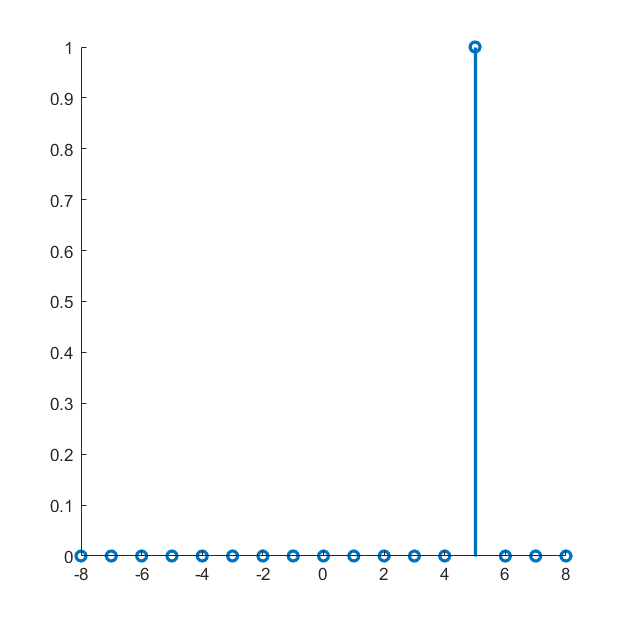

%%  单位抽样序列信号
clear all;
close all;
n=-8:8;
y=[zeros(1,13),1,zeros(1,3)];     %产生单位抽样序列
figure;
stem(n,y,'LineWidth',2);     
box off;
set(gcf,'position',[100,100,500,500]);

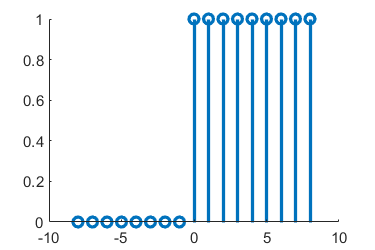

%%  单位阶跃序列
clear all;
close all;
n=-8:8;
yn=[zeros(1,8),ones(1,9)];
figure;
stem(n,yn,'LineWidth',2);
box off;
set(gcf,'position',[100,100,300,200]);

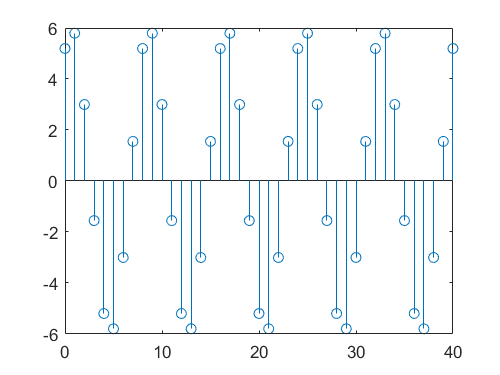

%% 正弦序列  角频率  相位
clear all;
close all;
n=0:40;
x=6*sin(pi*n/4+pi/3);     %幅值是6
figure;
stem(n,x);
set(gcf,'position',[200,200,400,300]);

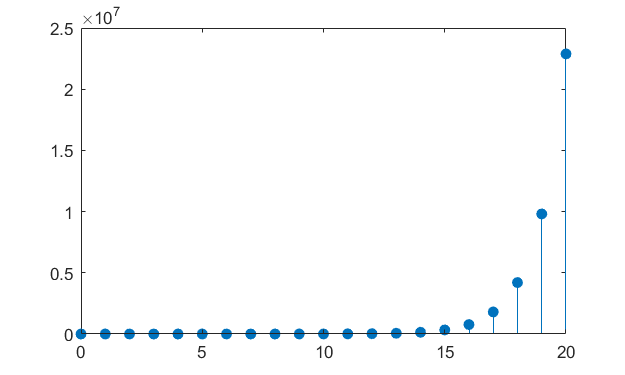


%%   实指数序列
clear all;
close all;
n=0:20;
x=(7/3).^n;
figure;
stem(n,x,'filled');
set(gcf,'position',[200,200,500,300]);

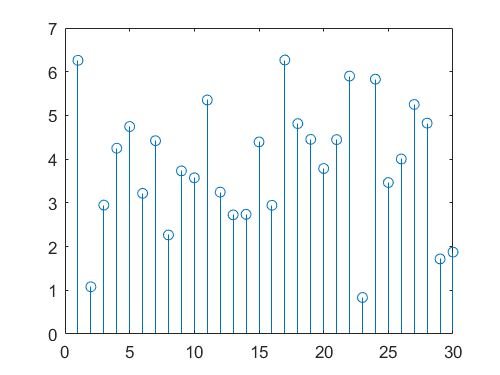

%%  随机序列    
clear all;
close all;
n=1:30;
x=4+sqrt(2)*randn(1,30);    
%randn产生均值为0  方差为1  的随机序列  均值为4 方差为2
figure;
stem(n,x);
set(gcf,'position',[200,200,400,300]);

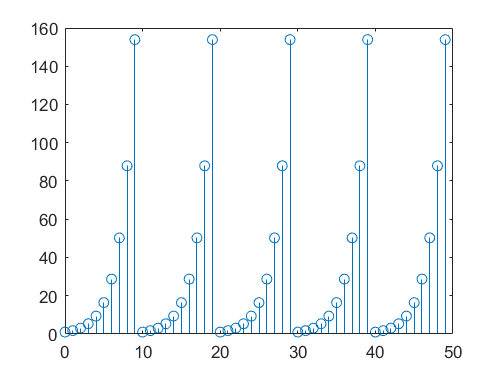

%%  周期序列
clear all;
close all;
n1=0:15;
x=(7/4).^n1;        %本来是指数序列
N=10;     %周期
k=5;      %周期的数目
n2=0:(k*N-1);
y=x(mod(n2,N)+1);    %    扩展成5个周期的信号
figure;
stem(n2,y);
set(gcf,'position',[200,200,400,300]); 

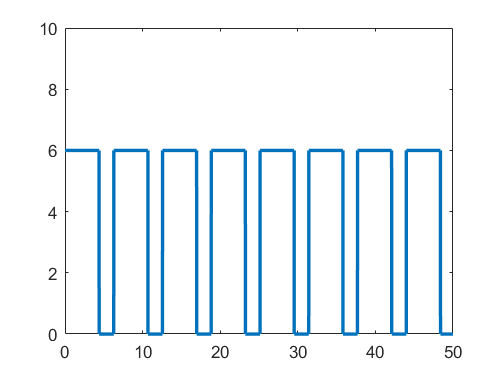

%%  方波信号
clear all;
close all;
t=0:0.01:50;
x=(square(t,70)+1)*3;       %方波   占空比是70
figure;
plot(t,x,'LineWidth',2);
axis([0,50,0,10]);          %坐标轴设置
set(gca,'xlim',[0 50]);
set(gcf,'position',[200,200,400,300]);

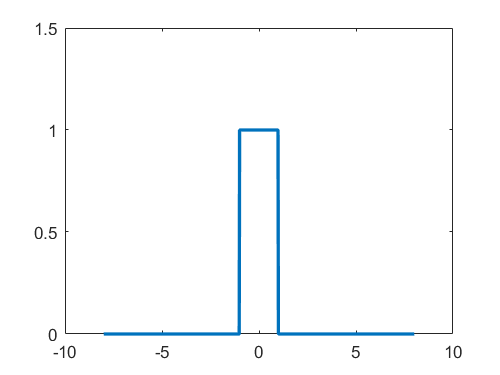

%%  矩形脉冲信号
clear all;
close all;
t=-8:0.02:8;
y=rectpuls(t,2);
figure;
plot(t,y,'LineWidth',2);
set(gca,'ylim',[0 1.5]);
set(gcf,'position',[200,200,400,300]);

%%   不同的脉冲序列
clear all;
close all;
t1=0:1/50e3:10e-3;
d1=[0:1/1e3:10e-3;0.8.^(0:10)]';
y1=pulstran(t1,d1,'gauspuls',10e3,0.5);  %  高斯脉冲序列
t2=0:1/1e3:1;
d2=0:1/3:1;
y2=pulstran(t2,d2,'rectpuls',0.2);       %  矩形脉冲序列
figure;
subplot(121);
plot(t1,y1);
subplot(122);
plot(t2,y2);
box off;
set(gca,'ylim',[0 1.2]);
set(gcf,'position',[200,200,800,300]);

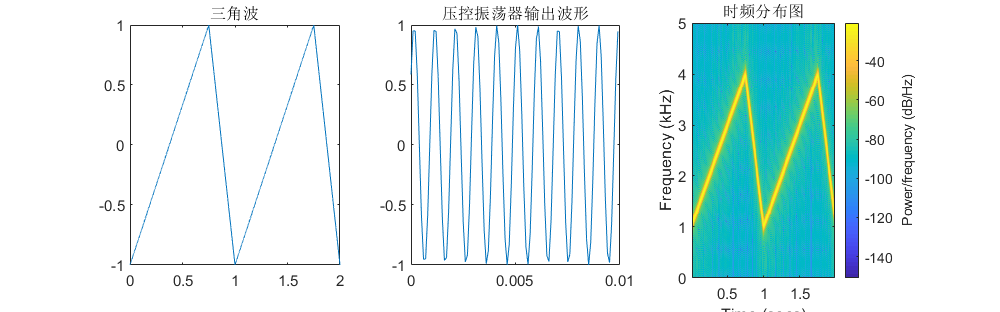

%%  压控震荡信号
clear all;
close all;
fs=10000;
t=0:1/fs:2;
y1=sawtooth(2*pi*t,0.75);     %先产生三角波
y2=vco(y1,[0.1 0.4]*fs,fs);    %三角波作为输入产生压控震荡信号
figure;
subplot(131);
plot(t,y1);
title('三角波');
subplot(132);
plot(t(1:100),y2(1:100));
title('压控振荡器输出波形');
subplot(133);
spectrogram(y2,kaiser(265,5),220,512,fs,'yaxis');  %画压控震荡信号的时频分布图
title('时频分布图');
set(gcf,'position',[200,200,800,250]);